## 计算共振角

这一步的目的是通过TMM计算共振角，并折算回相机端能够接收到的极角范围。之所以这么做是因为物场远场渐进表达式中分母项有nu1值，这个量在全内反射角处是0，从而导致被积函数是一个非连续函数，使得积分收敛缓慢，甚至发散。再者，由于SPCE能量几乎不会再共振角以内辐射出去，那么我这么干也是可以的。

#### 计算临界角

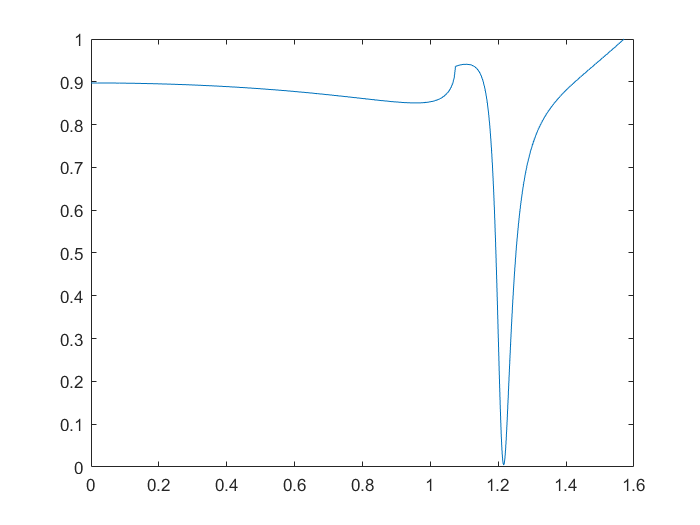

clear 
clc
d = [1e9 50 1e9];    % 各层厚度，单位nm
n = [1.515 0.13767 + 3.7917i 1.331];
theta = linspace(0,pi/2,1000);
R = zeros(size(theta));
for ii = 1:length(R)
    R(ii) = TMMR('p',670,theta(ii),d,n);
end
figure
plot(theta,abs(R).^2)

theta = 1.0948;

#### 计算积分上下限

n3 = 1.515; % 镜油折射率
n4 = 1; % 相机侧折射率
NA = 1.49;  % 数值孔径
mag = 60;   % 放大率
thetamax = asin(NA/n4/mag); % 成像透镜最大张角
thetamin = asin(n3*sin(theta)/n4/mag); % 成像透镜最大张角
thetatir = asin(n3*sin(1.07)/n4/mag); % 成像透镜最大张角

## 符号计算

syms theta1 theta3 theta4 phi px py pz n1 n3 nu1 nu3 tp ts
p = [px py pz].';   % 偶极子取向
s = [sin(theta3)*cos(phi) sin(theta3)*sin(phi) cos(theta3)].';  % 方向矢量
Edp = simplify(-cross(s,cross(s,p)));   % 偶极子远场电矢量

erho = [cos(phi) sin(phi) 0].'; % 柱坐标中径向基矢，对应p偏振光
es = [-sin(phi) cos(phi) 0].';  % 柱坐标中方位角基矢，对应s偏振光
ez = [0 0 1].'; % 柱坐标中z方向基矢
   
E3 = cos(theta3)*tp*(cos(theta1)*p.'*erho - sin(theta1)*p.'*ez)*erho ...
    + ts*p.'*es*es ...
    + sin(theta3)*tp*(-cos(theta1)*p.'*erho + sin(theta1)*p.'*ez)*ez    % 文中8式

$$E3 = \begin{array}{l} \left(\begin{array}{c} \mathrm{tp}\,\cos\left(\varphi \right)\,\cos\left(\theta_{3}\right)\,\sigma_{1}-\sin\left(\varphi \right)\,\left(\mathrm{py}\,\mathrm{ts}\,\cos\left(\varphi \right)-\mathrm{px}\,\mathrm{ts}\,\sin\left(\varphi \right)\right)\\ \cos\left(\varphi \right)\,\left(\mathrm{py}\,\mathrm{ts}\,\cos\left(\varphi \right)-\mathrm{px}\,\mathrm{ts}\,\sin\left(\varphi \right)\right)+\mathrm{tp}\,\cos\left(\theta_{3}\right)\,\sin\left(\varphi \right)\,\sigma_{1}\\ -\mathrm{tp}\,\sin\left(\theta_{3}\right)\,\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\mathrm{px}\,\cos\left(\varphi \right)\,\cos\left(\theta_{1}\right)-\mathrm{pz}\,\sin\left(\theta_{1}\right)+\mathrm{py}\,\cos\left(\theta_{1}\right)\,\sin\left(\varphi \right) \end{array}$$

% 镜油中电场渐进远场处电场表达式

L3 = [cos(theta3) 0 -sin(theta3);
    0 1 0;
    sin(theta3) 0 cos(theta3)]; 
% 物镜电场偏转矩阵，坐标系不动，偏振方向顺时针偏转θ角度后新坐标用此矩阵表示
L4 = [cos(theta4) 0 -sin(theta4);
    0 1 0;
    sin(theta4) 0 cos(theta4)];
% 成像透镜电场偏转矩阵，坐标系不动，偏振方向顺时针偏转θ角度后新坐标用此矩阵表示
R = [cos(phi) sin(phi) 0;
    -sin(phi) cos(phi) 0;
    0 0 1];
% 将坐标系由笛卡尔坐标系变换为柱坐标系

E4 = simplify(inv(R)*L4*L3*R*Edp)    

$$E4 = \left(\begin{array}{c} \mathrm{px}-\mathrm{px}\,{\cos\left(\varphi \right)}^{2}-\mathrm{py}\,\cos\left(\varphi \right)\,\sin\left(\varphi \right)-\mathrm{pz}\,\cos\left(\varphi \right)\,\cos\left(\theta_{4}\right)\,\sin\left(\theta_{3}\right)+\mathrm{px}\,{\cos\left(\varphi \right)}^{2}\,\cos\left(\theta_{3}\right)\,\cos\left(\theta_{4}\right)+\mathrm{py}\,\cos\left(\varphi \right)\,\cos\left(\theta_{3}\right)\,\cos\left(\theta_{4}\right)\,\sin\left(\varphi \right)\\ \mathrm{py}\,{\cos\left(\varphi \right)}^{2}+\mathrm{py}\,\cos\left(\theta_{3}\right)\,\cos\left(\theta_{4}\right)-\mathrm{px}\,\cos\left(\varphi \right)\,\sin\left(\varphi \right)-\mathrm{pz}\,\cos\left(\theta_{4}\right)\,\sin\left(\varphi \right)\,\sin\left(\theta_{3}\right)-\mathrm{py}\,{\cos\left(\varphi \right)}^{2}\,\cos\left(\theta_{3}\right)\,\cos\left(\theta_{4}\right)+\mathrm{px}\,\cos\left(\varphi \right)\,\cos\left(\theta_{3}\right)\,\cos\left(\theta_{4}\right)\,\sin\left(\varphi \right)\\ \sin\left(\theta_{4}\right)\,\left(\mathrm{px}\,\cos\left(\varphi \right)\,\cos\left(\theta_{3}\right)-\mathrm{pz}\,\sin\left(\theta_{3}\right)+\mathrm{py}\,\cos\left(\theta_{3}\right)\,\sin\left(\varphi \right)\right) \end{array}\right)$$

% 像空间中渐进远场表达式，文中没有乘R，肯定是错的，因为8式是笛卡尔坐标系下的电场

## 计算

#### 初始化数据

% 偶极子取向
px = 1;
py = 0;
pz = 0;
lambda = 670*1e-9;  % 波长
n4 = 1; % 各层折射率
n1 = 1.33;  % 溶液折射率
n2 = 0.13767 + 3.7917i; % 金膜折射率
n3 = 1.515; % 镜油折射率

d = 10*1e-9;    % 偶极子距离金膜距离
t = 50*1e-9;    % 金膜厚度
NA = 1.49;  % 数值孔径
mag = 60;   % 放大率
z = 0*1e-6; % 像方离焦情况
thetamax = asin(NA/n4/mag); % 成像透镜最大张角
k0 = 2*pi/lambda;   % 自由空间波矢    
k4 = 2*pi*n4/lambda;    % 像空间波矢

#### 定义相关函数

theta3 = @(theta4) asin(n4*sin(theta4)/n3*mag); % 通过出射角度推算入射角度
theta1 = @(theta4) asin(n3*sin(theta3(theta4))/n1); % 通过出射角度推算偶极子入射到金膜上的角度
alp = @(theta4) n3*sin(theta3(theta4)); % 物方横向有效折射率
nu1 = @(theta4) sqrt(n1^2 - alp(theta4).^2);   % 介质1中纵向有效折射率
nu3 = @(theta4) sqrt(n3^2 - alp(theta4).^2);   % 介质3中纵向有效折射率
phi_aberration = @(theta4) k0*nu1(theta4)*d...
    - k0*nu3(theta4)*d*n3/n1 - k0*nu3(theta4)*n3/n2*t;  % 像差函数

D = [1e9 t 1e9];    % 利用TMM计算透射系数
n = [n1 n2 n3];
ts = @(theta4) TMMT('s',lambda*1e9,theta1(theta4),D,n);
tp = @(theta4) TMMT('p',lambda*1e9,theta1(theta4),D,n);

x = linspace(-20,20,500)*mag*lambda;  % 物方观察视野大小
y = x;
[x,y] = meshgrid(x,y);
[phi,rho] = cart2pol(x,y);

#### 定义像场被积函数和积分简写

A = @(theta4) sqrt(cos(theta4)./cos(theta3(theta4))).*sin(theta4)...
    .*exp(1i*k4*z*cos(theta4)) ...
    .*exp(1i*phi_aberration(theta4)); ...
%     .*exp(1i*k0*(nu1(theta4)*d - nu3(theta4)*t)) ...  
%     .*nu3(theta4)./nu1(theta4); % A函数
    
f10 = @(theta4) A(theta4) ...
    .*(ts(theta4) + tp(theta4)*cos(theta1(theta4)).*cos(theta4)) ...
    .*besselj(0,k4*rho.*sin(theta4));
f11 = @(theta4) A(theta4) ...
    .*tp(theta4)*sin(theta1(theta4)).*cos(theta4) ...
    .*besselj(1,k4*rho.*sin(theta4));
f12 = @(theta4) A(theta4) ...
    .*(tp(theta4)*cos(theta1(theta4)).*cos(theta4) - ts(theta4)) ...
    .*besselj(2,k4*rho.*sin(theta4));
f20 = @(theta4) A(theta4) ...
    .*tp(theta4)*sin(theta1(theta4)).*sin(theta4) ...
    .*besselj(0,k4*rho.*sin(theta4));
f21 = @(theta4) A(theta4) ...
    .*tp(theta4)*cos(theta1(theta4)).*sin(theta4) ...
    .*besselj(1,k4*rho.*sin(theta4));
I10 = integral(f10,0,thetamax,'ArrayValued',1);
I11 = integral(f11,0,thetamax,'ArrayValued',1);
I12 = integral(f12,0,thetamax,'ArrayValued',1);
I20 = integral(f20,0,thetamax,'ArrayValued',1);
I21 = integral(f21,0,thetamax,'ArrayValued',1);
% I10 = integral(f10,thetamin,thetamax,'ArrayValued',1) ...
%     + integral(f10,0,thetatir,'ArrayValued',1);
% I11 = integral(f11,thetamin,thetamax,'ArrayValued',1) ...
%     + integral(f11,0,thetatir,'ArrayValued',1);
% I12 = integral(f12,thetamin,thetamax,'ArrayValued',1) ...
%     + integral(f12,0,thetatir,'ArrayValued',1);
% I20 = integral(f20,thetamin,thetamax,'ArrayValued',1) ...
%     + integral(f20,0,thetatir,'ArrayValued',1);
% I21 = integral(f21,thetamin,thetamax,'ArrayValued',1) ...
%     + integral(f21,0,thetatir,'ArrayValued',1);

#### 计算结果

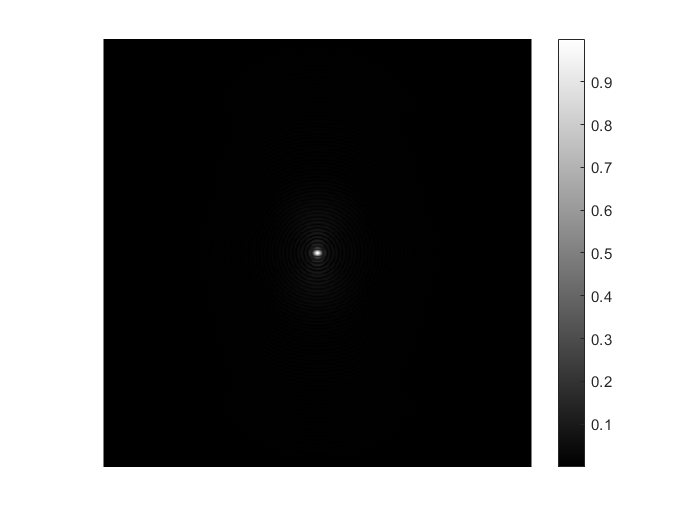

Ex = px*I10/2 - 1i*pz*I11.*cos(phi) - (px*cos(2*phi) + py*sin(2*phi)).*I12/2;
Ey = py*I10/2 - 1i*pz*I11.*sin(phi) - (px*sin(2*phi) - py*cos(2*phi)).*I12/2;
Ez = -pz*I20 + 1i*(px*cos(phi) + py*sin(phi)).*I21;
E_amp = sqrt(abs(Ex).^2+abs(Ey).^2+abs(Ez).^2);
P = max(E_amp,[],'all');    % 电场强度归一化常数

figure
imagesc(abs(Ex)/P)
axis off
axis square
colormap(gray)
colorbar

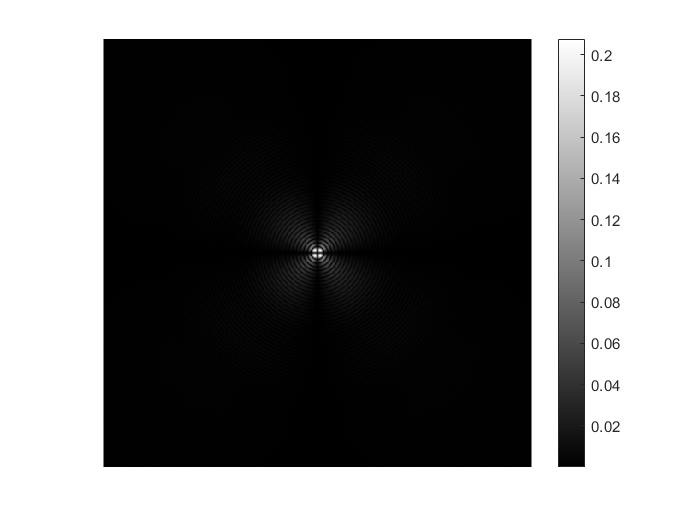


figure
imagesc(abs(Ey)/P)
axis off
axis square
colormap(gray)
colorbar

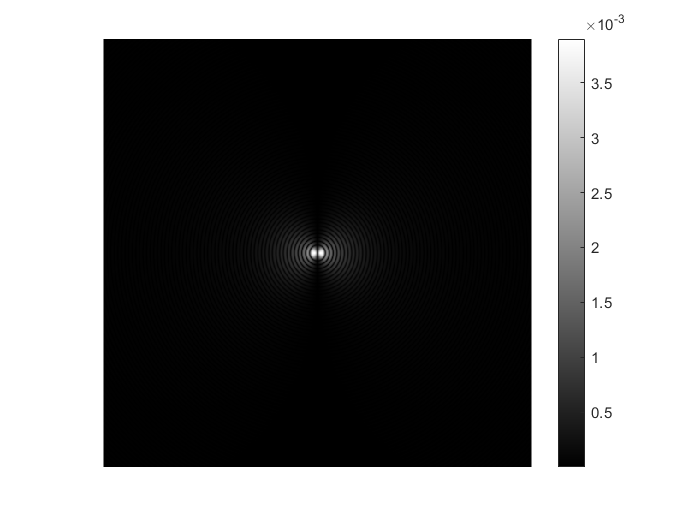


figure
imagesc(abs(Ez)/P)
axis off
axis square
colormap(gray)
colorbar

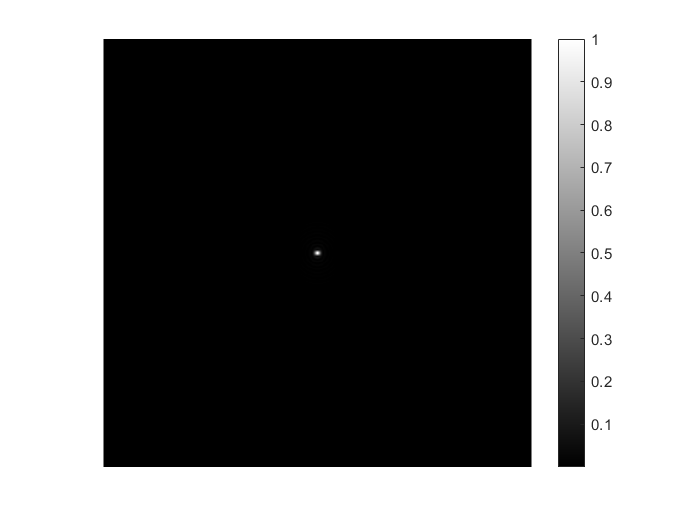


figure
imagesc((E_amp/P).^2)
axis off 
axis square
colormap(gray)
colorbar

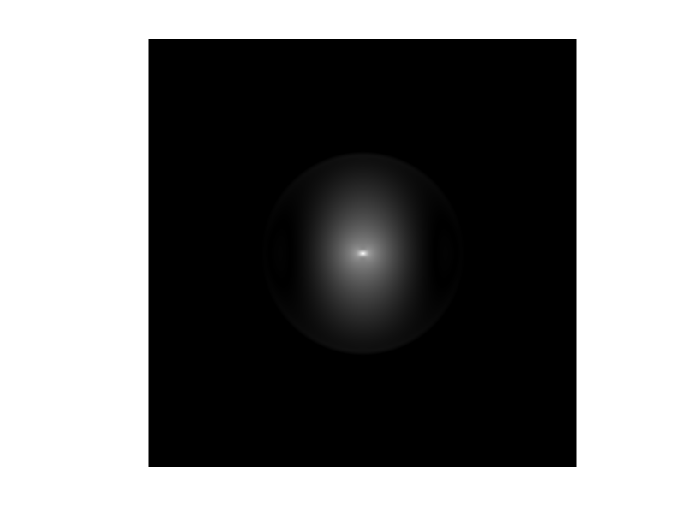


imagesc(abs(fftshift(fft2(fftshift((E_amp/P).^2)))))
axis off 
axis square

## 符号比对

当三层介质折射率变成一样的时候，原文的远场辐射公式退化为偶极辐射的远场公式，所以这里的处理是想看看公式有没有写错

clear
syms px py pz theta phi Ts Tp nu1 nu3 n1 n3 
p = [px py pz].';
erho = [cos(phi) sin(phi) 0].';
es = [-sin(phi) cos(phi) 0].';
ez = [0 0 1].';
s = [sin(theta)*cos(phi) sin(theta)*sin(phi) cos(theta)].';
Edp = -simplify(cross(s,cross(s,p)))

$$Edp = \begin{array}{l} \left(\begin{array}{c} \cos\left(\theta \right)\,\left(\mathrm{px}\,\cos\left(\theta \right)-\mathrm{pz}\,\cos\left(\varphi \right)\,\sin\left(\theta \right)\right)-\sin\left(\varphi \right)\,\sin\left(\theta \right)\,\sigma_{1}\\ \cos\left(\theta \right)\,\left(\mathrm{py}\,\cos\left(\theta \right)-\mathrm{pz}\,\sin\left(\varphi \right)\,\sin\left(\theta \right)\right)+\cos\left(\varphi \right)\,\sin\left(\theta \right)\,\sigma_{1}\\ -\sin\left(\theta \right)\,\left(\mathrm{px}\,\cos\left(\varphi \right)\,\cos\left(\theta \right)-\mathrm{pz}\,\sin\left(\theta \right)+\mathrm{py}\,\cos\left(\theta \right)\,\sin\left(\varphi \right)\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\mathrm{py}\,\cos\left(\varphi \right)\,\sin\left(\theta \right)-\mathrm{px}\,\sin\left(\varphi \right)\,\sin\left(\theta \right) \end{array}$$

alp = n3*sin(theta);
E_inf = simplify(nu3/n1/n3*Tp*(nu1*p.'*erho - alp*p.'*ez)*erho ...
    + Ts*p.'*es*es ...
    + alp/n1/n3*Tp*(-nu1*p.'*erho + alp*p.'*ez)*ez)

$$E\_inf = \begin{array}{l} \left(\begin{array}{c} \frac{\mathrm{Tp}\,\nu_{3}\,\cos\left(\varphi \right)\,\sigma_{1}}{n_{1}\,n_{3}}-\mathrm{Ts}\,\sin\left(\varphi \right)\,\left(\mathrm{py}\,\cos\left(\varphi \right)-\mathrm{px}\,\sin\left(\varphi \right)\right)\\ \mathrm{Ts}\,\cos\left(\varphi \right)\,\left(\mathrm{py}\,\cos\left(\varphi \right)-\mathrm{px}\,\sin\left(\varphi \right)\right)+\frac{\mathrm{Tp}\,\nu_{3}\,\sin\left(\varphi \right)\,\sigma_{1}}{n_{1}\,n_{3}}\\ -\frac{\mathrm{Tp}\,\sin\left(\theta \right)\,\sigma_{1}}{n_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\nu_{1}\,\mathrm{px}\,\cos\left(\varphi \right)+\nu_{1}\,\mathrm{py}\,\sin\left(\varphi \right)-n_{3}\,\mathrm{pz}\,\sin\left(\theta \right) \end{array}$$

E_inf = simplify(cos(theta)*(cos(theta)*p.'*erho - sin(theta)*p.'*ez)*erho ...
    + p.'*es*es ...
    + sin(theta)*(-cos(theta)*p.'*erho + sin(theta)*p.'*ez)*ez)

$$E\_inf = \begin{array}{l} \left(\begin{array}{c} \cos\left(\varphi \right)\,\cos\left(\theta \right)\,\sigma_{1}-\sin\left(\varphi \right)\,\left(\mathrm{py}\,\cos\left(\varphi \right)-\mathrm{px}\,\sin\left(\varphi \right)\right)\\ \cos\left(\varphi \right)\,\left(\mathrm{py}\,\cos\left(\varphi \right)-\mathrm{px}\,\sin\left(\varphi \right)\right)+\cos\left(\theta \right)\,\sin\left(\varphi \right)\,\sigma_{1}\\ -\sin\left(\theta \right)\,\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\mathrm{px}\,\cos\left(\varphi \right)\,\cos\left(\theta \right)-\mathrm{pz}\,\sin\left(\theta \right)+\mathrm{py}\,\cos\left(\theta \right)\,\sin\left(\varphi \right) \end{array}$$

## 远场辐射图

#### 初始化

clear
p = [1 1i 1].';  % 偶极子取向
n = [1.33 0.13767+3.7917i 1.51];
lambda = 670*1e-9;  % 波长
n1 = n(1);  % 第一层介质折射率
n2 = n(2);  % 第二层介质折射率
n3 = n(3);  % 第三层介质折射率

d = 10*1e-9;    % 偶极子距离金膜距离，单位m
t = 50*1e-9;    % 金膜厚度，单位m
k0 = 2*pi/lambda;   % 自由空间波矢   

phi = 0;

#### 定义基矢

erho = [cos(phi) sin(phi) 0].';
es = [-sin(phi) cos(phi) 0].';
ez = [0 0 1].';
s = @(theta) [sin(theta)*cos(phi) sin(theta)*sin(phi) cos(theta)].';
Edp = @(theta) -cross(s(theta),cross(s(theta),p));

#### 定义相关函数

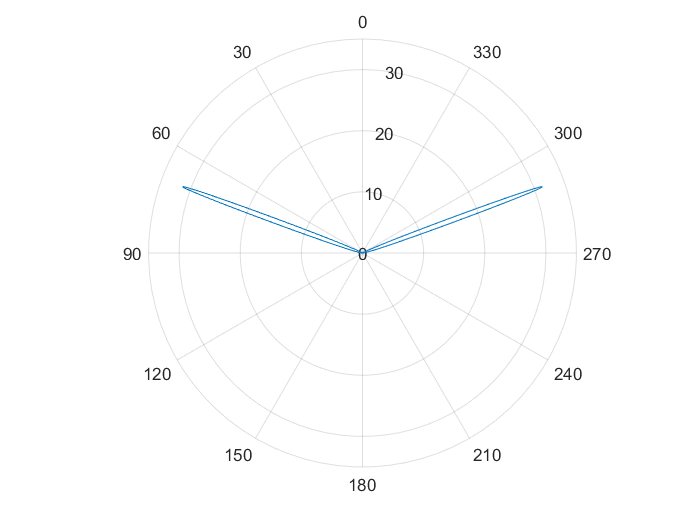

% 利用TMM计算透射系数
D = [1e9 t*1e9 1e9];    
n = [n1 n2 n3];

alp = @(theta) n3*sin(theta);
theta1 = @(theta) asin(alp(theta)/n1); % 通过出射角度推算偶极子入射到金膜上的角度
Ts = @(theta) TMMT('s',lambda*1e9,theta1(theta),D,n);
Tp = @(theta) TMMT('p',lambda*1e9,theta1(theta),D,n);
nu1 = @(theta) sqrt(n1^2 - alp(theta)^2);
nu3 = @(theta) sqrt(n3^2 - alp(theta)^2);

E_inf = @(theta) ( ...
    nu3(theta)/n1/n3*Tp(theta)*(nu1(theta)*p.'*erho - alp(theta)*p.'*ez)*erho ...
    + Ts(theta)*p.'*es*es ...
    + alp(theta)/n1/n3*Tp(theta)*(-nu1(theta)*p.'*erho + alp(theta)*p.'*ez)*ez ...
    ) ...
    *nu3(theta)/nu1(theta)*exp(1i*k0*(nu1(theta)*d - nu3(theta)*t));

theta = linspace(-pi/2,pi/2,2000);
for ii = 1:2000
    R(ii) = norm(E_inf(theta(ii)));   % 反射场模值
end

figure
polarplot(theta,R.^2)  
% rlim([0 10])
ax = gca;
ax.ThetaZeroLocation = 'top';